clear

AR = 8.5;
Sweep = 0;
Taper = 0.53;
c_bar = 3.54;
srefref = 101;
fuselage_rad = 1.25;
twist = -3*pi/180;
panelnum = 100;
Uinf = 1;

incidence = 1*pi/180;


airfoil(1).Field = 'root';
airfoil(1).alpha0 = -0.07;
airfoil(1).a = 6.68;
airfoil(2).Field = 'tip';
airfoil(2).alpha0 = -0.07;
airfoil(2).a = 6.68;


%% discritize planform to plot
[Sref, c_y, span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)

Sref = 100.1566

c_y =     4.4871    4.4857    4.4842    4.4828    4.4814    4.4799    4.4785    4.4770    4.4756    4.4741    4.4727    4.4712    4.4698    4.4683    4.4669    4.4654    4.4640    4.4626    4.4611    4.4597    4.4582    4.4568    4.4553    4.4539    4.4524    4.4510    4.4495    4.4481    4.4467    4.4452    4.4438    4.4423    4.4409    4.4394    4.4380    4.4365    4.4351    4.4336    4.4322    4.4308    4.4293    4.4279    4.4264    4.4250    4.4235    4.4221    4.4206    4.4192    4.4177    4.4163


span_disc =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


quarterchord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


MACpos = 656


semispan = length(span_disc)*0.01

semispan = 14.5900


thetadist = acos(span_disc/span_disc(end))

thetadist =     1.5708    1.5701    1.5694    1.5687    1.5681    1.5674    1.5667    1.5660    1.5653    1.5646    1.5639    1.5633    1.5626    1.5619    1.5612    1.5605    1.5598    1.5591    1.5585    1.5578    1.5571    1.5564    1.5557    1.5550    1.5543    1.5536    1.5530    1.5523    1.5516    1.5509    1.5502    1.5495    1.5488    1.5482    1.5475    1.5468    1.5461    1.5454    1.5447    1.5440    1.5434    1.5427    1.5420    1.5413    1.5406    1.5399    1.5392    1.5386    1.5379    1.5372



twist_dis = linspace(0,twist,length(span_disc))

twist_dis =          0   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0010   -0.0010   -0.0010   -0.0011   -0.0011   -0.0011   -0.0012   -0.0012   -0.0013   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0015   -0.0015   -0.0015   -0.0016   -0.0016   -0.0017   -0.0017   -0.0017   -0.0018


alpha_0_dis = linspace(airfoil(1).alpha0,airfoil(2).alpha0,length(span_disc))

alpha_0_dis =    -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700


incidence_dis = incidence*ones(1,length(span_disc))

incidence_dis =     0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175


alpha_dis = twist_dis - alpha_0_dis + incidence_dis

alpha_dis =     0.0875    0.0874    0.0874    0.0873    0.0873    0.0873    0.0872    0.0872    0.0872    0.0871    0.0871    0.0871    0.0870    0.0870    0.0870    0.0869    0.0869    0.0868    0.0868    0.0868    0.0867    0.0867    0.0867    0.0866    0.0866    0.0866    0.0865    0.0865    0.0864    0.0864    0.0864    0.0863    0.0863    0.0863    0.0862    0.0862    0.0862    0.0861    0.0861    0.0861    0.0860    0.0860    0.0859    0.0859    0.0859    0.0858    0.0858    0.0858    0.0857    0.0857



a_dis = linspace(airfoil(1).a,airfoil(2).a,length(span_disc))

a_dis =     6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800



mu_dis = (a_dis.*c_y)/(4.*AR*c_bar)

mu_dis =     0.2490    0.2490    0.2489    0.2488    0.2487    0.2486    0.2486    0.2485    0.2484    0.2483    0.2482    0.2482    0.2481    0.2480    0.2479    0.2478    0.2478    0.2477    0.2476    0.2475    0.2474    0.2474    0.2473    0.2472    0.2471    0.2470    0.2470    0.2469    0.2468    0.2467    0.2466    0.2465    0.2465    0.2464    0.2463    0.2462    0.2461    0.2461    0.2460    0.2459    0.2458    0.2457    0.2457    0.2456    0.2455    0.2454    0.2453    0.2453    0.2452    0.2451



LHS = zeros(floor(panelnum/2),1);
RHS = zeros(floor(panelnum/2),floor(panelnum/2));

for i = 1:floor(panelnum/2)
    for j = 1 : floor(panelnum/2)
%         tempind = floor((i*length(span_disc)/panelnum - length(span_disc)/(2*panelnum)));
        [temp,tempind]= min(abs(thetadist-i*pi/panelnum));
        LHS(i,1) = mu_dis(tempind)*alpha_dis(tempind)*sin(thetadist(tempind));
        RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
    end
end
Aseries = RHS\LHS;
gamma_span_coef = 4*semispan*Uinf;
gamma_sum = 0;

for n = 1:floor(panelnum/2)
    gamma_sum = gamma_sum + Aseries(n)*sin(n*thetadist);
end

gamma_plot = gamma_span_coef*gamma_sum

gamma_plot =     0.6880    0.6879    0.6878    0.6877    0.6876    0.6875    0.6874    0.6873    0.6872    0.6871    0.6870    0.6869    0.6868    0.6867    0.6866    0.6865    0.6864    0.6863    0.6862    0.6861    0.6860    0.6859    0.6858    0.6857    0.6856    0.6855    0.6854    0.6853    0.6852    0.6851    0.6850    0.6848    0.6847    0.6846    0.6845    0.6844    0.6843    0.6842    0.6841    0.6840    0.6839    0.6838    0.6837    0.6836    0.6835    0.6834    0.6832    0.6831    0.6830    0.6829


gamma_ellipse = 4*semispan*Uinf*Aseries(1)*sin(thetadist)

gamma_ellipse =     0.7272    0.7272    0.7272    0.7272    0.7272    0.7272    0.7272    0.7272    0.7272    0.7272    0.7272    0.7272    0.7272    0.7272    0.7271    0.7271    0.7271    0.7271    0.7271    0.7271    0.7271    0.7271    0.7271    0.7271    0.7271    0.7271    0.7271    0.7271    0.7270    0.7270    0.7270    0.7270    0.7270    0.7270    0.7270    0.7270    0.7270    0.7269    0.7269    0.7269    0.7269    0.7269    0.7269    0.7269    0.7268    0.7268    0.7268    0.7268    0.7268    0.7268


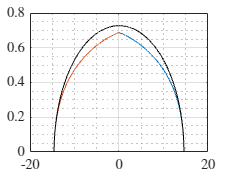

plot(semispan*cos(thetadist),gamma_plot)
hold on
plot(-semispan*cos(thetadist),gamma_plot)

plot(-semispan*cos(thetadist),gamma_ellipse,'k')
plot(semispan*cos(thetadist),gamma_ellipse,'k')

grid on
grid minor


hold off


MACcord = span_disc(MACpos)

MACcord = 6.5500

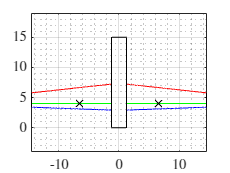

longitudinalMACac =  4;
fuselagedatum = 0;
feselageend = 15;


% plot(span_disc,c_y,'.')
% x_engine = quarterchord(ceil(length(c_y)*0.37))
% height_engine0.37*max(span_disc)*tand(5)-0.175*c_y(ceil(length(c_y)*0.37))-0.9
LEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) - 0.25 .* c_y;
TEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) + 0.75 .* c_y;
quarterchordplot = (quarterchord-quarterchord(MACpos) + longitudinalMACac);
%origin at quarterchord point of root chord
plot (span_disc(fuselage_rad*100:end),LEsweep(fuselage_rad*100:end),'b')
hold on
plot (span_disc(fuselage_rad*100:end),TEsweep(fuselage_rad*100:end),'r')
plot (span_disc(fuselage_rad*100:end),quarterchordplot(fuselage_rad*100:end),'g')
plot (span_disc(MACpos),quarterchordplot(MACpos),'xk')

plot (-span_disc(fuselage_rad*100:end),TEsweep(fuselage_rad*100:end),'r')
hold on
plot (-span_disc(fuselage_rad*100:end),LEsweep(fuselage_rad*100:end),'b')
plot (-span_disc(fuselage_rad*100:end),quarterchordplot(fuselage_rad*100:end),'g')
plot (-span_disc(MACpos),quarterchordplot(MACpos),'xk')

plot ([span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)], [LEsweep(fuselage_rad*100),TEsweep(fuselage_rad*100)],'k')
plot ([span_disc(end),span_disc(end)], [LEsweep(end),TEsweep(end)],'k')
plot ([-span_disc(fuselage_rad*100),-span_disc(fuselage_rad*100)], [LEsweep(fuselage_rad*100),TEsweep(fuselage_rad*100)],'k')
plot ([-span_disc(end),-span_disc(end)], [LEsweep(end),TEsweep(end)],'k')

plot ([span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuselage_rad*100),-span_disc(fuselage_rad*100)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[fuselagedatum,fuselagedatum],'k')
plot ([-span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[feselageend,feselageend],'k')

ylim([-7.5 7.5])
axis equal
hold off
grid on
grid minor

chordpos = 0;

Cl_alpha = 6.68

Cl_alpha = 6.6800

Mach = 0.45

Mach = 0.4500

S_rat = (Sref-2*fuselage_rad*c_y(fuselage_rad*100))/Sref

S_rat = 0.8925

FLF = 1.07*(1+(2*fuselage_rad/(semispan*2)))^2

FLF = 1.2612

yetaest = 0;
CL_alpha_curve = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)

CL_alpha_curve = 5.8697

function [Sref, c_y,span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)
s_1 = 0.25 * AR * (1+Taper); %_1 using 1 as reference root chord length
Sref_1 = (1 + Taper) * s_1;
span_disc_1 = [0:0.01:s_1];
c_y_1 = 1 - ((1-Taper)/s_1) * span_disc_1;
c_bar_1 = 2*trapz(span_disc_1,(c_y_1).^2)/Sref_1;
ratio = c_bar/c_bar_1; % dimensionalize using c_bar, can be changed later to root or tip chord length
s = ratio*s_1;
Sref = ratio * (1 + Taper) * s;
span_disc = [0:0.01:s];
c_y =  (1 - ((1-Taper)/s) * span_disc)*ratio;
temp1 = (c_y - c_bar).^2;
MACpos = find(temp1 == min(temp1));
quarterchord =  span_disc .* tand(Sweep);
end
function [CL_alpha_curve] = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)
beta = (1-Mach^2)^0.5;
if yetaest == 0
    yeta = Cl_alpha/(2*pi/beta);
else
    yeta = yetaest;
end
CL_alpha_curve = 2*pi*AR/(2+(4+((AR^2*beta^2)/(yeta^2))*(1+(tand(Sweep))^2/(beta^2)))^0.5) * S_rat * FLF;
end